# 62743 DSP — Week 12 Torsdag

% FIR LP Design: Fourier Transform, Windows & Frequency Sampling

close all; clear; clc;

%  General paths (for Obsidian image embedding)

imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end

## Common filter parameters (Exercise 1)

Fs    = 8000;          % Sampling frequency [Hz]
Fc    = 2000;          % Cut-off frequency [Hz]
Ntaps = 23;            % Number of taps
M     = Ntaps - 1;
K     = M/2;

wc = 2*pi*Fc/Fs;       % digital cutoff = pi/2

fprintf('Exercise 1 setup:\n');

Exercise 1 setup:


fprintf('  Fs   = %d Hz\n', Fs);

  Fs   = 8000 Hz


fprintf('  Fc   = %d Hz\n', Fc);

  Fc   = 2000 Hz


fprintf('  Ntaps= %d, M = %d, K = %d\n\n', Ntaps, M, K);

  Ntaps= 23, M = 22, K = 11



## Exercise 1-A: Ideal LP impulse response (Fourier transform method)

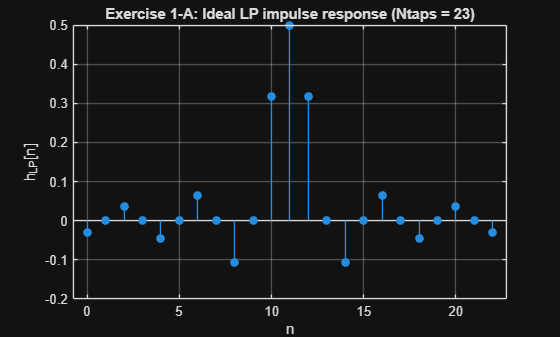

n       = 0:M;
n_shift = n - K;

hLP = (wc/pi) * sinc((wc/pi)*n_shift);   % ideal LP, causal

figure;
stem(n, hLP, 'filled'); grid on;
xlabel('n'); ylabel('h_{LP}[n]');
title('Exercise 1-A: Ideal LP impulse response (Ntaps = 23)');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1A_impulse.png'), 'Resolution', 300);

## Exercise 1-B: Magnitude response vs normalized angular frequency

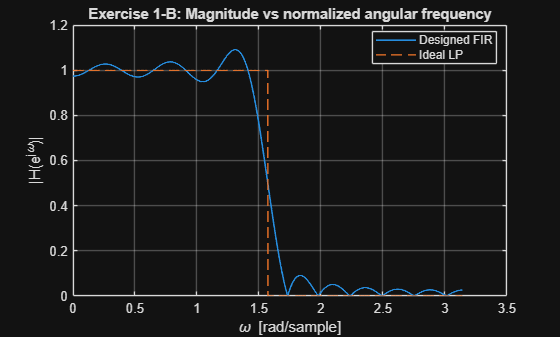

Nw = 2048;
[H_LP, w] = freqz(hLP, 1, Nw);   % w in [0, pi]

% Ideal square LP
Hideal = double(w <= wc);

figure;
plot(w, abs(H_LP), 'LineWidth', 1.2); hold on; grid on;
plot(w, Hideal, '--', 'LineWidth', 1.0);
xlabel('\omega [rad/sample]');
ylabel('|H(e^{j\omega})|');
title('Exercise 1-B: Magnitude vs normalized angular frequency');
legend('Designed FIR', 'Ideal LP', 'Location', 'best');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1B_mag_norm_w.png'), 'Resolution', 300);

## Exercise 1-C: Magnitude & log-magnitude vs frequency

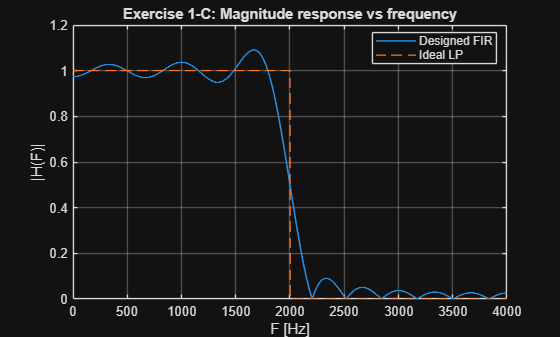

F   = w * Fs / (2*pi);              % Hz
HdB = 20*log10(abs(H_LP) + eps);

figure;
plot(F, abs(H_LP), 'LineWidth', 1.2); hold on; grid on;
plot(F, Hideal, '--', 'LineWidth', 1.0);
xlabel('F [Hz]');
ylabel('|H(F)|');
title('Exercise 1-C: Magnitude response vs frequency');
legend('Designed FIR', 'Ideal LP', 'Location', 'best');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1C_mag_vs_F.png'), 'Resolution', 300);

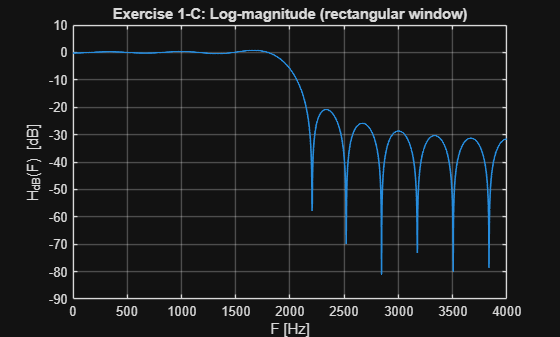


figure;
plot(F, HdB, 'LineWidth', 1.2); grid on;
xlabel('F [Hz]');
ylabel('H_{dB}(F) [dB]');
title('Exercise 1-C: Log-magnitude (rectangular window)');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1C_logmag_rect.png'), 'Resolution', 300);


idx_stop   = F > Fc;
[peakSL, ~] = max(HdB(idx_stop));
fprintf('Rectangular: first side-lobe peak ≈ %.2f dB\n\n', peakSL);

Rectangular: first side-lobe peak ≈ -6.12 dB



## Exercise 1-D/E: Hamming window expression & coefficients

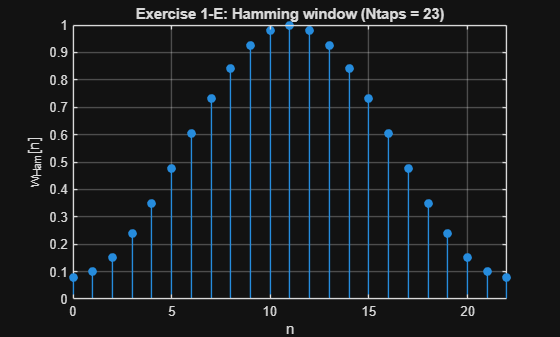

n  = 0:M;
wH = 0.54 - 0.46*cos(2*pi*n/M);

figure;
stem(n, wH, 'filled'); grid on;
xlabel('n');
ylabel('w_{Ham}[n]');
title('Exercise 1-E: Hamming window (Ntaps = 23)');
xlim([0 M]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1E_hamming_window.png'), 'Resolution', 300);

## Exercise 1-F: Windowed impulse response

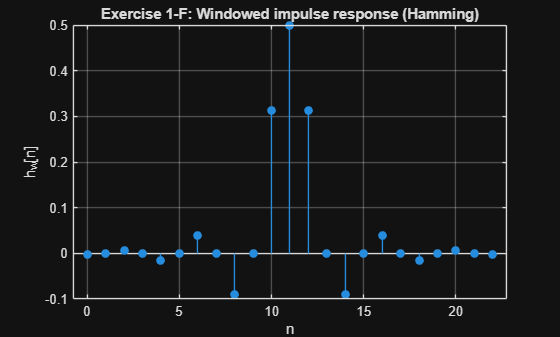

hW = hLP .* wH;

figure;
stem(n, hW, 'filled'); grid on;
xlabel('n'); ylabel('h_w[n]');
title('Exercise 1-F: Windowed impulse response (Hamming)');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1F_hw_impulse.png'), 'Resolution', 300);

## Exercise 1-G: Log-magnitude for windowed filter & comparison

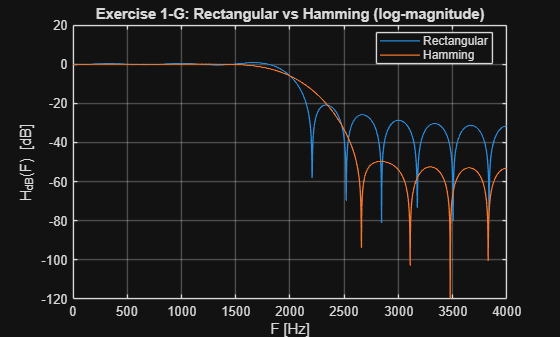

[H_W, wW] = freqz(hW, 1, Nw);
FW        = wW * Fs / (2*pi);
HdB_W     = 20*log10(abs(H_W) + eps);

figure;
plot(F, HdB,   'LineWidth', 1.0); hold on; grid on;
plot(FW, HdB_W,'LineWidth', 1.0);
xlabel('F [Hz]');
ylabel('H_{dB}(F) [dB]');
title('Exercise 1-G: Rectangular vs Hamming (log-magnitude)');
legend('Rectangular', 'Hamming', 'Location', 'best');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_1G_logmag_rect_vs_ham.png'), 'Resolution', 300);


idx_stop_W   = FW > Fc;
[peakSL_W, ~] = max(HdB_W(idx_stop_W));
fprintf('Hamming: first side-lobe peak ≈ %.2f dB\n\n', peakSL_W);

Hamming: first side-lobe peak ≈ -6.07 dB



## Exercise 2: FIR via frequency sampling technique

Ntaps_fs = 7;
M_fs     = Ntaps_fs - 1;    % 6
K_fs     = M_fs/2;          % 3
wc_fs    = 0.3*pi;          % cutoff [rad]

fprintf('Exercise 2 setup:\n');

Exercise 2 setup:


fprintf('  Ntaps = %d, M = %d, K = %d\n', Ntaps_fs, M_fs, K_fs);

  Ntaps = 7, M = 6, K = 3


fprintf('  omega_c = 0.3*pi ≈ %.3f rad\n\n', wc_fs);

  omega_c = 0.3*pi ≈ 0.942 rad




% 2-B: Frequency grid
k_fs    = 0:K_fs;
omega_k = 2*pi*k_fs/(M_fs+1);     % 2*pi*k/7

% 2-C/D: Desired H[k]
Hk = zeros(size(k_fs));
pass_idx = omega_k <= wc_fs;
Hk(pass_idx) = exp(-1j*omega_k(pass_idx)*K_fs);   % e^{-j omega_k K}

disp('k, omega_k, H[k]:');

k, omega_k, H[k]:


disp(table(k_fs.', omega_k.', Hk.', ...
    'VariableNames', {'k','omega_k','Hk'}));

    k    omega_k           Hk        
    _    _______    _________________

    0         0            1+0i      
    1    0.8976     -0.90097-0.43388i
    2    1.7952            0+0i      
    3    2.6928            0+0i      




% 2-E: Compute b0..bK using formula
b0K = zeros(1, K_fs+1);
for n_idx = 0:K_fs
    sum_val = 0;
    for kk = 1:K_fs
        sum_val = sum_val + Hk(kk+1)*cos(2*pi*kk*(n_idx-K_fs)/(2*K_fs+1));
    end
    b0K(n_idx+1) = (1/(2*K_fs+1))*( Hk(1) + 2*sum_val );
end

% 2-F: Extend by symmetry
b_fs = zeros(1, M_fs+1);
b_fs(1:K_fs+1)   = b0K;
b_fs(K_fs+2:end) = fliplr(b0K(1:K_fs));

fprintf('\nFrequency-sampling FIR coefficients (b_fs):\n');


Frequency-sampling FIR coefficients (b_fs):


disp(b_fs.');

   0.3748 + 0.1117i
   0.2001 + 0.0276i
  -0.0176 - 0.0773i
  -0.1146 - 0.1240i
  -0.0176 - 0.0773i
   0.2001 + 0.0276i
   0.3748 + 0.1117i




% (Optional) compare to values in solution sheet if desired:
% b_expected = [0.1146 0.0793 0.3210 0.4286 0.3210 0.0793 0.1146];


## Exercise 2-H: Magnitude & phase response (freqz)

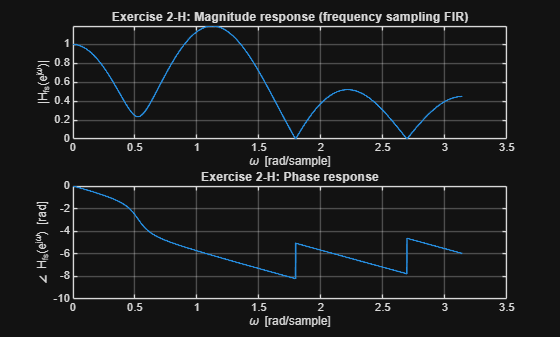

Nw_fs      = 2048;
[H_fs, w_fs] = freqz(b_fs, 1, Nw_fs);

figure;
subplot(2,1,1);
plot(w_fs, abs(H_fs), 'LineWidth', 1.2); grid on;
xlabel('\omega [rad/sample]');
ylabel('|H_{fs}(e^{j\omega})|');
title('Exercise 2-H: Magnitude response (frequency sampling FIR)');

subplot(2,1,2);
plot(w_fs, unwrap(angle(H_fs)), 'LineWidth', 1.2); grid on;
xlabel('\omega [rad/sample]');
ylabel('\angle H_{fs}(e^{j\omega}) [rad]');
title('Exercise 2-H: Phase response');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Torsdag_2H_mag_phase_freq_sampling.png'), 'Resolution', 300);